In this second optimization version, we have added a couple of items that should make computations much quicker.

- Using **interpolation** to create a polynomial based on Eo'(-1), Eo'(0) and Eo'(1). Then, find the maximum of this polynomial (really cheap computationally speaking) and use the maximum value of ρ as an initial guess to find the maximum of Eo(ρ) - ρ*R.

- Add a **check step** to determine if the transmission rate R is greater than Eo'(0) or less than Eo'(1). If R > Eo'(0), the optimal ρ is 0. If R < Eo'(1), the optimal ρ is 1. Otherwise, we simply need to compute the optimization problem as usual.

clc; clear;

function E = compute_E0_1(SNR, Q, X)
    % Ensure Q and X are column vectors
    Q = Q(:);
    X = X(:);
    
    % Compute pairwise squared Euclidean distances between all points in X
    dist_sq = pdist2(X, X, 'squaredeuclidean');
    
    % Create matrix of Q(x)*Q(x_hat) probabilities
    Q_outer = Q * Q';
    
    % Compute exponential term for all pairs
    exp_term = exp(-SNR/4 * dist_sq);
    
    % Calculate the weighted sum
    weighted_sum = sum(Q_outer(:) .* exp_term(:));
    
    % Final result
    E = -log2(weighted_sum);
end

% System parameters
N = 20;          % Number of quadrature nodes
SNR = 1;         % Signal-to-Noise Ratio
M = 64;           % Constellation size
d = 2;           % Distance parameter
R = 0.5;         % Communication rate

% Compute Gauss-Hermite nodes and weights
[nodes, weights] = GaussHermite_Locations_Weights(N);

% Generate and normalize PAM constellation
X = generatePAMConstellation(M, d);
X = X / sqrt(mean(X.^2));  % Normalize to unit energy

% Initialize probability distribution (1×M)
Q = repmat(1/M, 1, M);
Q = Q';

% Define Gaussian function
G = @(z) exp(-abs(z).^2)/pi;

% Create matrices
tic;
pi_matrix = createPiMatrix(M, N, weights);
z_matrix = createComplexNodesMatrix(nodes);
g_matrix = createGMatrix(X, z_matrix, SNR, G);
matrix_time = toc;

fprintf('Matrix creation time: %.2f ms\n', matrix_time*1000);

Matrix creation time: 151.76 ms


% Initial guess
rho = 0;
% Calculation of all values - F and E0s, and its derivatives
tic;
[F0, E0, dF0, dE0, d2F0, d2E0] = derivativesE0(Q, pi_matrix, g_matrix, rho)

F0 =    3.141592653589761


E0 =      1.489593324273944e-14


dF0 =   -1.692640722283985


dE0 =    0.777301402604024


d2F0 =    2.426238934165314


d2E0 =   -0.695389603836675


round(toc*1000)

ans =     67


% Calculation for E0'(1)
E0_1 = compute_E0_1(SNR, Q, X)

E0_1 =    0.531276278861357


E0p_0 = computeFirstDerivativeE0(Q, pi_matrix, g_matrix, 0)

E0p_0 =    0.777301402604024


E0p_1 = computeFirstDerivativeE0(Q, pi_matrix, g_matrix, 1)

E0p_1 =    0.357132772942273


max_iter = 1000;       % Maximum iterations for the loop
tol = 1e-7;            % Convergence tolerance
tol_curvature = 1e-10; % Curvature tolerance

if R > E0p_0
    rho_opt = 0;
elseif R < E0p_1
    rho_opt = 1;
else
    iter = uint32(0);  % Use uint32 for counter
    log2_const = log(2);  % Precompute constant
    rho = 0;         % Initial guess for rho
    
    while (iter < max_iter)
        % Compute all derivatives in one pass to avoid redundant calculations
        [F0, E0, dF0, dE0, d2F0, d2E0] = derivativesE0(Q, pi_matrix, g_matrix, rho);

        % Optimize divisions by precomputing repeated values
        f_inv = 1/F0;
        fp_f = dF0 * f_inv;

        % Compute gradient and curvature with minimized operations
        gradient = (-fp_f / log2_const) - R;
        curvatura = -((d2F0 * f_inv) - (fp_f * fp_f)) / log2_const;
        
        % Combine convergence checks to reduce branching
        if abs(gradient/curvatura) < tol || abs(curvatura) < tol_curvature
            break;
        end
        
        disp(rho);

        % Compute new rho value and clamp to [0, 1]
        rho_new = rho - gradient / curvatura;
    
        % Check convergence based on rho change
        if abs(rho_new - rho) < tol
            break;
        end
    
        rho = rho_new;
        iter = iter + 1;
    end
    rho_opt = rho; % Assign the optimized value
    fprintf('\nIterations: %.2f\n', iter);
end

     0

   0.398771280263709

   0.526305778573533

   0.535541227264447




Iterations: 4.00


fprintf('Optimisation time: %.2f ms\n', round(toc*1000));

Optimisation time: 308.00 ms



rho_opt

rho_opt =    0.535584714323228


Eo_max = computeEoForRhoExponential(rho_opt, Q, pi_matrix, g_matrix) - rho_opt * R

Eo_max =    0.066905669508869



A = computeEoForRhoExponential(0, Q, pi_matrix, g_matrix)

A =      1.489593324273944e-14


C = computeEoForRhoExponential(1, Q, pi_matrix, g_matrix)

C =    0.531276278861374


B = computeFirstDerivativeE0(Q, pi_matrix, g_matrix, 0)

B =    0.777301402604024


D = computeFirstDerivativeE0(Q, pi_matrix, g_matrix, 1)

D =    0.357132772942273


Approx. maximum of P(rho) is 0.5313 at rho = 1.0000


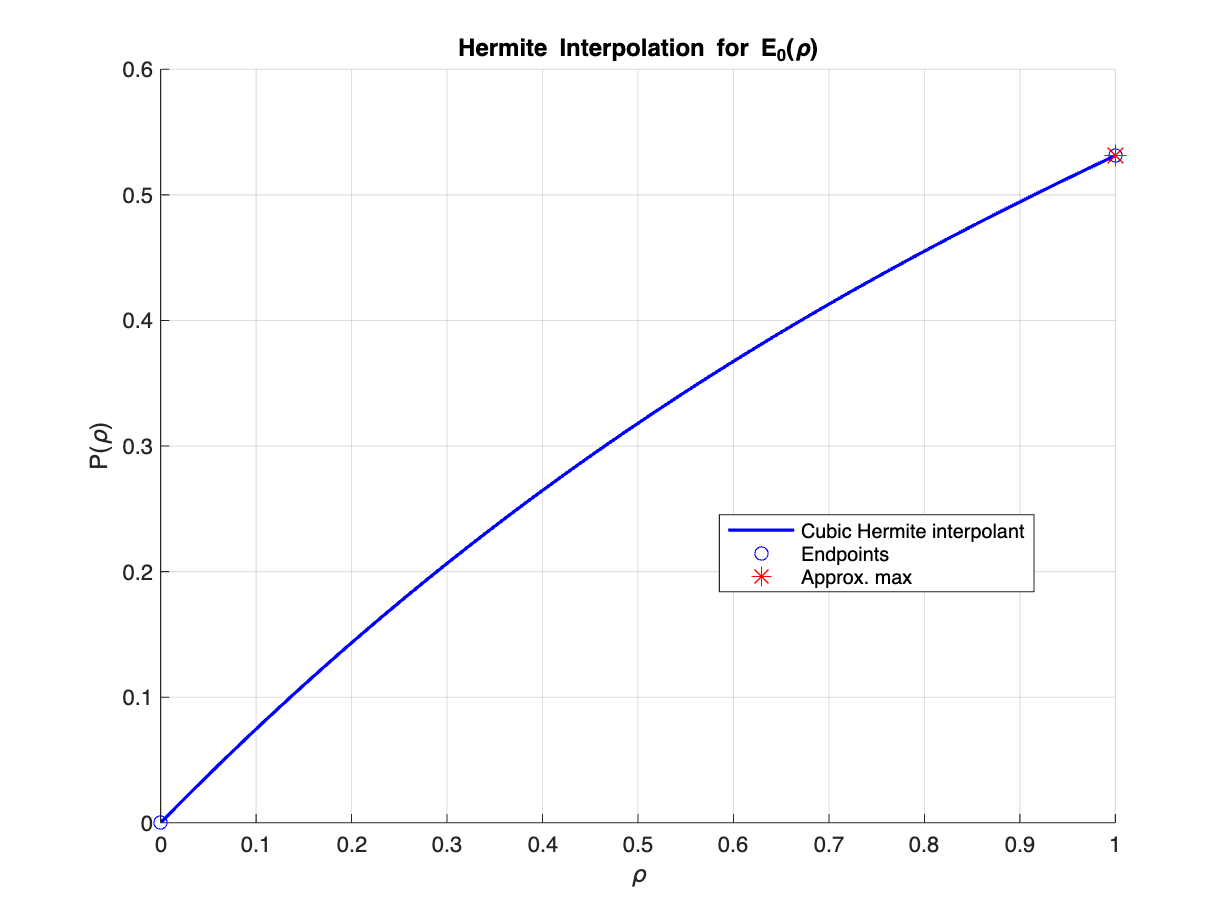

% INPUTS:
%   A = E0(0)
%   B = E0'(0)
%   C = E0(1)
%   D = E0'(1)
demoHermiteInterpolation(A, B, C, D)

rho_test = linspace(0, 1, 1000);   % 100 points in [0,1]
values   = p(rho_test);          % P(rho) at each point
derivs   = dp(rho_test);         % P'(rho) at each point

